## **Heavy Frame**

 AERO60002 Aerospace Vehicle Design 2024-2025

**Project G1**

% Housekeeping
clear
clc
close all

### **0 Design Parameters**

**0.1 Sea Level**

[T0, a0, P0, rho0] = atmosisa(0);  % Sea level condition
g = 9.80665;                       % Standard acceleration of gravity (m/s^2)

**0.2 Fuselage Properties**

D = 6.38;                          % Fuselage diameter (m)
r = D ./ 2;                        % Fuselage radius (m)
C = 2 * pi * r;                    % Fuselage circumference (m)

**0.3 Material Properties**

E_f = 67000000000;                 % Young's Modulus (N/m^2)
rho_f = 2860;                      % Density (kg/m^3)
sigma_y = 614000000;               % Tensile yield stress (Pa)
tau_y = sigma_y ./ sqrt(3);        % Shear yield stress (Pa)

pi * sqrt(E_f/sigma_y)

ans = 32.8173

**0.4 Critical Loading Conditions**

Q = 4.753206271377147e+06;        % Maximum shear force (N)
P = 0;                            % Maximum tangential load (N)
T = 0;                            % Maximum torque (Nm)

### **1 WISE curve**

**1.1 Find WISE curve**

% Define theta range (0 to 2*pi for full fuselage section)
theta = linspace(0, 2 * pi, 1000);

% Compute shear flow distributions for P, Q, and T load cases
M_P = -(P * r / (2 * pi)) .* ((3 * sin(theta) / 2) + (pi - theta) .* (cos(theta) - 1));
N_P = -(P / (2 * pi)) .* ((sin(theta) / 2) - (pi - theta) .* cos(theta));
S_P = -(P / (2 * pi)) .* (((pi - theta) .* sin(theta)) - 1 - (cos(theta) / 2));

M_Q = -(Q * r / (2 * pi)) .* ((cos(theta) / 2) - (pi - theta) .* sin(theta) + 1);
N_Q = -(Q / (2 * pi)) .* ((3 * cos(theta) / 2) + (pi - theta) .* sin(theta));
S_Q = -(Q / (2 * pi)) .* (((pi - theta) .* cos(theta)) - (sin(theta) / 2));

M_T = -(T / (2 * pi)) .* (pi - 2 * sin(theta) - theta);
N_T = -(T / (2 * pi * r)) .* ((3 * cos(theta) / 2) + (pi - theta) .* sin(theta));
S_T = -(T / (2 * pi * r)) .* (1 + 2 * cos(theta));

% Compute total shear flow distributions
M_total = M_P + M_Q + M_T;
N_total = N_P + N_Q + N_T;
S_total = S_P + S_Q + S_T;

1.2 Plotting the result

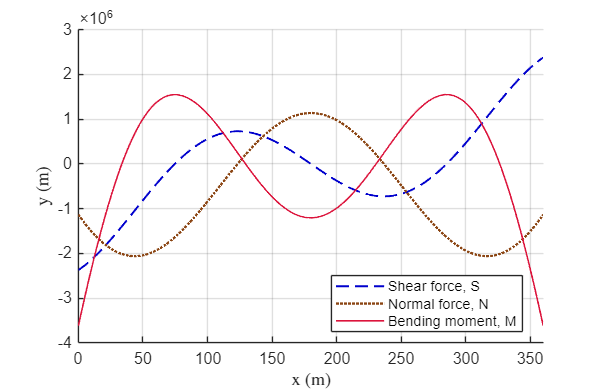

figure(1)

clf;

hold on;

plot(theta * 180 / pi, S_total, '--', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.25);
plot(theta * 180 / pi, N_total, ':', 'Color', [139/255 69/255 19/255], 'LineWidth', 1.5);
plot(theta * 180 / pi, M_total, '-', 'Color', [220/255 20/255 60/255], 'LineWidth', 1.);

% Legends
legend("Shear force, S", "Normal force, N", "Bending moment, M", "Location", "best", 'NumColumns', 1, FontSize = 9)

% Axis labels with LaTeX font
xlabel('x (m)', 'Interpreter', 'latex');
ylabel('y (m)', 'Interpreter', 'latex');

% Set plot limits and grid
xlim([0 360]);
grid on;

hold off;

% Set figure size
set(gcf, 'Position', [0 0 500 325]);

1.3 Find the maximum

S_max = max(abs(S_total))

S_max = 2.3766e+06

N_max = max(abs(N_total))

N_max = 2.0637e+06

M_max = max(abs(M_total))

M_max = 3.6198e+06

### **2 Optimisation Problem using fmincon with Global research**

compare [fmincon](https://www.mathworks.com/help/optim/ug/fmincon.html) with [GlobalSearch](https://ww2.mathworks.cn/help/gads/globalsearch.html) and [ga](https://ww2.mathworks.cn/help/gads/ga.html), using the best result

**2.0 Initial conditions**

Define the objective function for optimisation problem

fun = @(x) mass_hf(x(1), x(2), x(3), x(4));            % (t_web, t_fl, b_f, h_f)

Define initial point for the objective function

x0 = [25 / 1000, 30 / 1000, 300 / 1000, 400 / 1000];   % take average from literiture review

Boundary conditions

lb = [1 / 1000, 1 / 1000, 100 / 1000, 100 / 1000]; % change dynamically
ub = [0.06, 0.06, 0.5, 0.5];                           % change dynamically

Nonlinear constraints

nonlcon = @Non_linear_hf_2;

**2.1 Define problem**

Create optimization problem [createOptimProblem](https://ww2.mathworks.cn/help/gads/createoptimproblem.html)

problem = createOptimProblem('fmincon', 'objective', fun, 'x0', x0, 'lb', lb, 'ub', ub, 'nonlcon', nonlcon, 'options', optimoptions('fmincon', 'Display', 'iter'));

[GlobalSearch](https://ww2.mathworks.cn/help/gads/globalsearch.html)

gs = GlobalSearch('NumTrialPoints', 10000, 'MaxWaitCycle', 200);

**2.2 Run optimisation**

[x_opt, f_opt] = fmincon(fun, x0, [], [], [], [], lb, ub, nonlcon)


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x_opt =     0.0291    0.0436    0.3108    0.3814


f_opt = 2.1890e+03

[x_opt, f_opt] = run(gs, problem);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    1.605072e+03    2.331e+08    1.657e+03
    1      10    1.607487e+03    2.300e+08    1.494e+03    7.825e-04
    2      15    1.664650e+03    2.026e+08    1.335e+03    5.278e-03
    3      20    1.671279e+03    1.995e+08    1.365e+03    5.935e-03
    4      25    1.851477e+03    1.279e+08    6.892e+03    1.614e-02
    5      30    1.894134e+03    1.128e+08    8.352e+03    8.368e-03
    6      35    1.894650e+03    1.126e+08    8.366e+03    4.667e-05
    7      40    1.926734e+03    1.019e+08    9.018e+03    4.352e-03
    8      45    1.928018e+03    1.015e+08    9.043e+03    1.688e-04
    9      50    1.934294e+03    9.850e+07    9.220e+03    7.081e-04
   10      55    1.986549e+03    7.464e+07    1.064e+04    5.855e-03
   11      60    1.986831e+03    7.451e+07    1.065e+04    3.086e-05
   12      65    1.986833e+03    7.451e+07    1

### **3 Validate Result**

**3.1 Assign x values**

t_web = x_opt(1); % web thickness (m)
t_web * 1000      % 15-25 mm

ans = 29.0672

t_fl = x_opt(2);  % flange thickness (m)
t_fl * 1000       % 25-40 mm

ans = 43.6008


b_f = x_opt(3);   % frame width (m)
b_f * 1000        % 200-400 mm

ans = 310.7777

h_f = x_opt(4);   % frame height (m)
h_f * 1000        % 300-500 mm

ans = 381.4139

**2.2 Calculate mass**

% Find second moment of inertia
[I_x, A] = I_hf(t_web, t_fl, b_f, h_f);
I_x * 1000 ^ 4

ans = 1.1243e+09


A * 1000 ^ 2

ans = 3.8187e+04


% Calcualte frame mass
m_f = rho_f * A * C

m_f = 2.1890e+03

**2.3 Calculate constraint**

% Slenderness ratio
1.2 * sqrt(E_f/sigma_y)

ans = 12.5353

(h_f / t_web) - 1.2 * sqrt(E_f/sigma_y)

ans = 0.5865

h_f / t_web

ans = 13.1218

0.7 * sqrt(E_f/sigma_y)

ans = 7.3123

(b_f / t_fl) - 0.7 * sqrt(E_f/sigma_y)

ans = -0.1845

b_f / t_fl

ans = 7.1278


%
% Maximum direct stress
N_max / A - sigma_y

ans = -5.5996e+08

(sigma_y)  / 1e6

ans = 614

(N_max / A)  / 1e6

ans = 54.0423


%
% Maximum shear stress
Q_x = b_f * t_fl * (h_f/2 - t_fl/2);
(S_max * Q_x) / (I_x * t_web) - tau_y

ans = -1.8805e+08

tau_y  / 1e6

ans = 354.4931

((S_max * Q_x) / (I_x * t_web)) / 1e6

ans = 166.4399


%
% Maximum bending stress
(M_max * h_f) / (2 * I_x) - sigma_y

ans = -0.0136

sigma_y / 1e6

ans = 614

((M_max * h_f) / (2 * I_x)) / 1e6

ans = 614.0000

### **4 Buckling analysis**

% From ESDU datasheet 
% (see Structure 3 Lecture Notes for k to K calculation)
Kc = 3.69; % 3.62 for v = 0.3
Ks = 4.93; % 4.83 for v = 0.3
% Flange Local Buckling:
BCf = Kc * E_f * ((t_fl / b_f) ^ 2);
BCf / 1e6

ans = 4.8662e+03

% Web Shear Buckling:
BCw = Ks * E_f * ((t_web / h_f) ^ 2);
BCw / 1e6

ans = 1.9184e+03

% Web compressive Buckling:
BCw2 = Kc * E_f * ((t_web / h_f) ^ 2);
BCw2 / 1e6

ans = 1.4359e+03